Declaration of variables

clc;
clear;

Road_length  =200;

Road_length = 1

car_number   = 15

car_number = 15

acceleration =6

acceleration = 0.0500

deceleration = -0.0400

deceleration =-6.5
%initial speed
u = 5
%time limitis
time =200

time = 130

%limit speed
lim = 15

lim = 1

%initial position of car
J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


%A = rand(1,car_number).*Road_length
%x(J,1)= sort(A)
x(J,1) = (Road_length/car_number) *J

x =     0.0667
    0.1333
    0.2000
    0.2667
    0.3333
    0.4000
    0.4667
    0.5333
    0.6000
    0.6667


v =     0.7788
    0.4235
    0.0908
    0.2665
    0.1537
    0.2810
    0.4401
    0.5271
    0.4574
    0.8754


v(J,1)=randi([0,car_number],car_number,1)
%minimum distance between cars
x0 = Road_length/(car_number*2)

x0 = 0.0333

num = car_number-1

num = 14

delT = 0.1

delT = 0.1000

k = time / delT

k = 1300

%
average(1) = 0

average = 0

t(1) = 0

t = 0

initialize road

for T=2:k
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T)*delT;
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


x(J,T)=x(J,T)

x =     0.0667    0.1495    0.2374    0.3303    0.4192    0.5041    0.5849    0.6618    0.7347    0.8036    0.8685    0.9293    0.9862    0.0391    0.0970    0.1599    0.2278    0.3006    0.3785    0.4614    0.5403    0.6152    0.6860    0.7529    0.8158    0.8747    0.9296    0.9804    0.0273    0.0792    0.1361    0.1980    0.2648    0.3277    0.3866    0.4415    0.4924    0.5392    0.5911    0.6480    0.7099    0.7768    0.8486    0.9165    0.9804    0.0403    0.1052    0.1750    0.2499    0.3298
    0.1333    0.1807    0.2330    0.2904    0.3527    0.4111    0.4654    0.5158    0.5621    0.6044    0.6428    0.6771    0.7075    0.7428    0.7832    0.8285    0.8789    0.9342    0.9855    0.0329    0.0852    0.1426    0.2049    0.2723    0.3446    0.4220    0.5043    0.5917    0.6840    0.7813    0.8747    0.9640    0.0494    0.1397    0.2351    0.3351    0.4351    0.5351    0.6351    0.7351    0.8311    0.9231    0.0111    0.1041    0.2021    0.3021    0.4021    0.5021    0.6021    0

v(J,T)=v(J,T)

v =     0.7788    0.8288    0.8788    0.9288    0.8888    0.8488    0.8088    0.7688    0.7288    0.6888    0.6488    0.6088    0.5688    0.5288    0.5788    0.6288    0.6788    0.7288    0.7788    0.8288    0.7888    0.7488    0.7088    0.6688    0.6288    0.5888    0.5488    0.5088    0.4688    0.5188    0.5688    0.6188    0.6688    0.6288    0.5888    0.5488    0.5088    0.4688    0.5188    0.5688    0.6188    0.6688    0.7188    0.6788    0.6388    0.5988    0.6488    0.6988    0.7488    0.7988
    0.4235    0.4735    0.5235    0.5735    0.6235    0.5835    0.5435    0.5035    0.4635    0.4235    0.3835    0.3435    0.3035    0.3535    0.4035    0.4535    0.5035    0.5535    0.5135    0.4735    0.5235    0.5735    0.6235    0.6735    0.7235    0.7735    0.8235    0.8735    0.9235    0.9735    0.9335    0.8935    0.8535    0.9035    0.9535    1.0000    1.0000    1.0000    1.0000    1.0000    0.9600    0.9200    0.8800    0.9300    0.9800    1.0000    1.0000    1.0000    1.0000    1

average(T) = average(T)

average =          0    0.5496    0.5874    0.6237    0.6490    0.6624    0.6764    0.6904    0.6984    0.7064    0.7052    0.7098    0.7205    0.7372    0.7366    0.7500    0.7606    0.7675    0.7781    0.7854    0.7941    0.8034    0.8107    0.8158    0.8232    0.8305    0.8360    0.8413    0.8506    0.8572    0.8608    0.8702    0.8735    0.8728    0.8735    0.8713    0.8639    0.8546    0.8566    0.8546    0.8579    0.8613    0.8606    0.8633    0.8693    0.8719    0.8713    0.8706    0.8726    0.8719


k_1 = floor(k/3);
d_av = average(1,(k_1):k)

d_av =     0.8693    0.8667    0.8753    0.8733    0.8827    0.8880    0.8913    0.8933    0.8993    0.9060    0.9113    0.9140    0.9093    0.8940    0.8987    0.9073    0.9107    0.9253    0.9320    0.9353    0.9393    0.9387    0.9380    0.9233    0.9180    0.9087    0.9053    0.9047    0.9013    0.8980    0.8973    0.8987    0.9013    0.9100    0.9013    0.8980    0.8867    0.8840    0.8820    0.8767    0.8680    0.8747    0.8813    0.8887    0.8947    0.8980    0.9040    0.8967    0.9047    0.9047


mean = mean(d_av)

mean = 0.8418

Plot

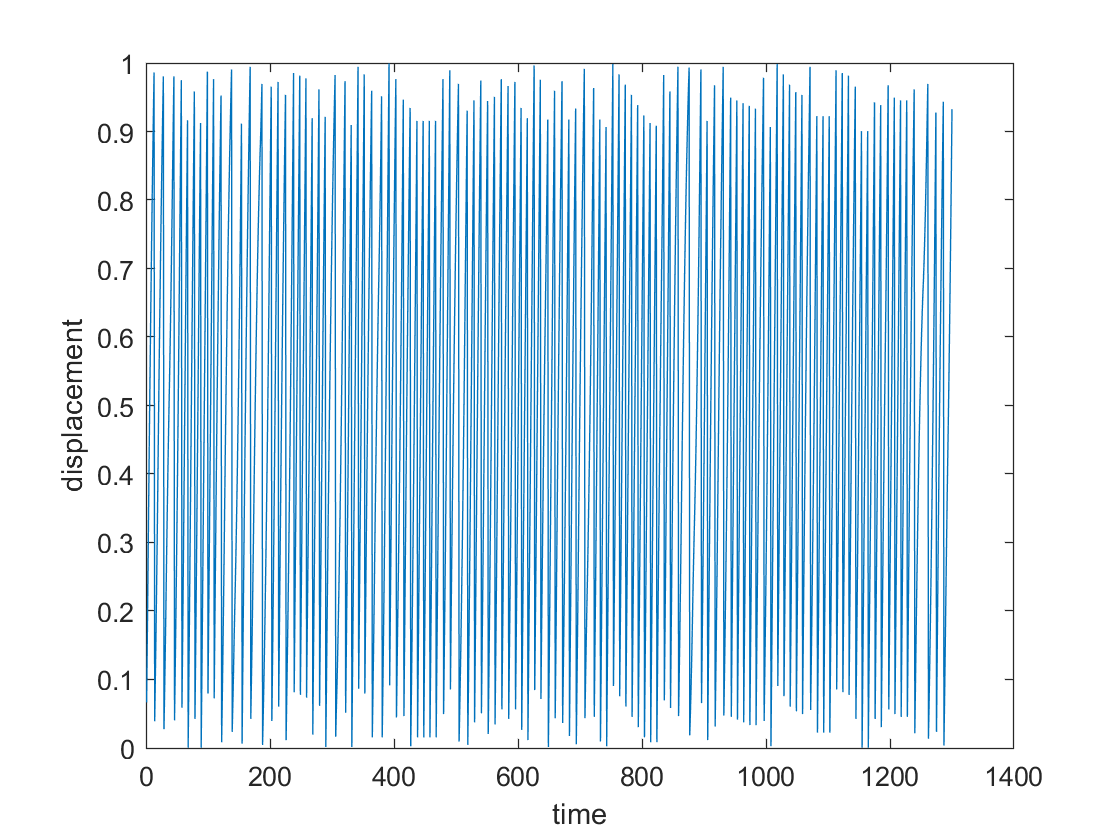

plot(x(1,:),".","MarkerSize",2);
hold on
for b = 2: car_number
    plot(x(b,:),".","MarkerSize",2)
end
xlabel('time')
ylabel('displacement')
hold off;

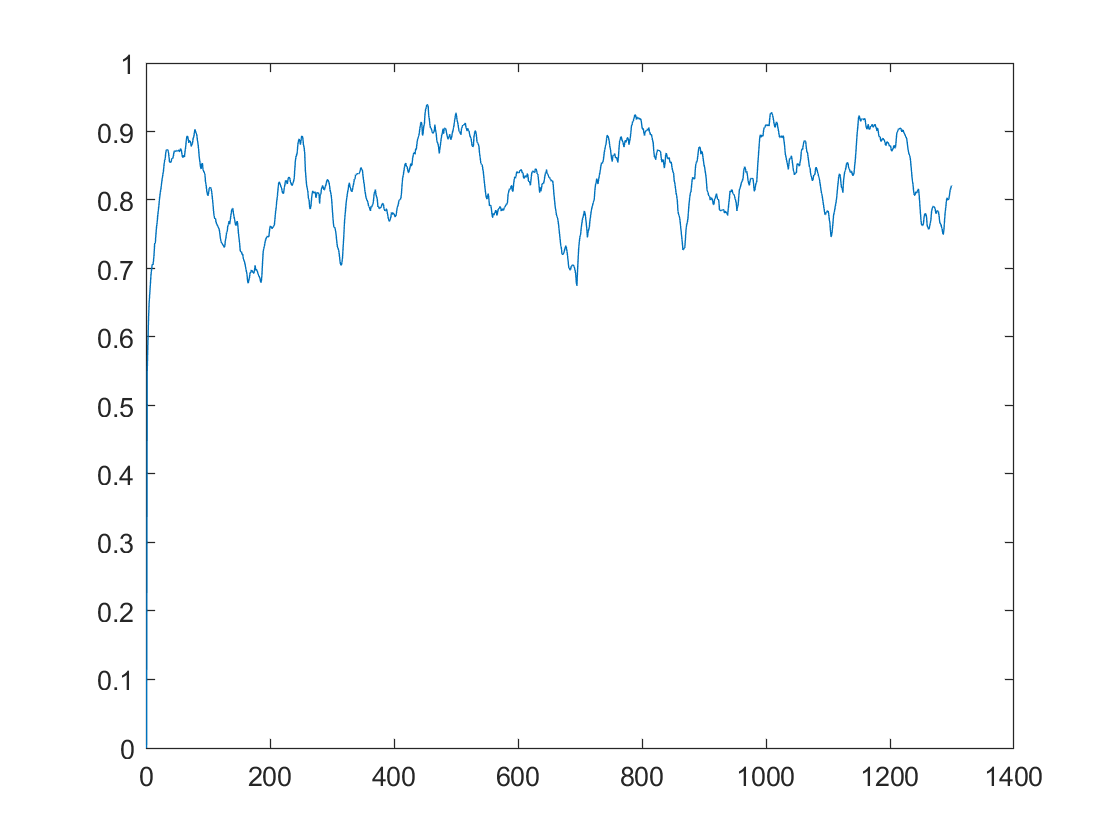

plot(average)